## EEGEMGのみ

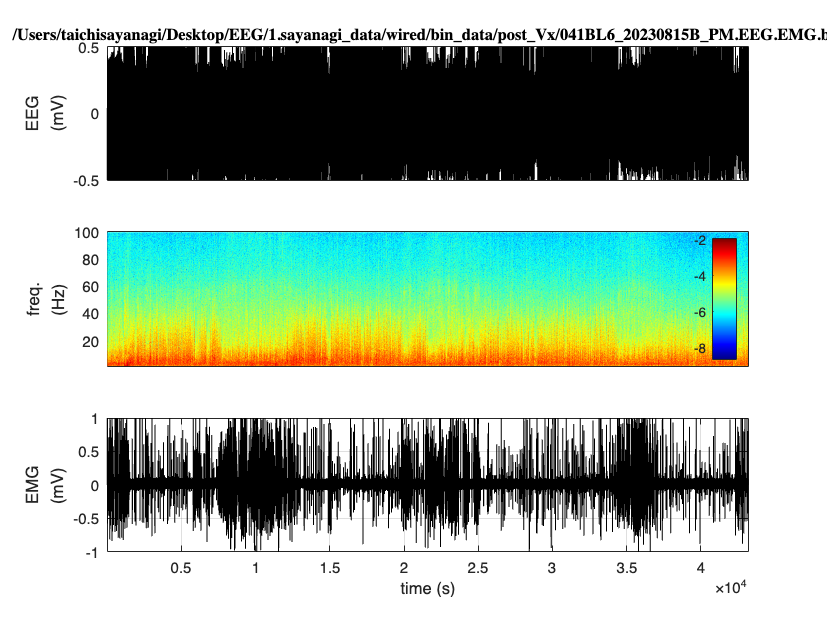

Error using fft
FFT length must be a nonnegative integer scalar.

clearvars;
FL.SR = 1000;% Sampling Rate (Hz), FluoLescence
const.ch = 2;% 6 ch rec.
const.span = 99;%for smooth
const.DefaultPath = '/Users/taichisayanagi/Library/CloudStorage/OneDrive-個人用/1. WORK/1. MEDICINE/1. Neurosurgery/7.research/Kenji.Lab/EEG';%'C:\Users\pdp\Documents\data';
% Cameleon: ex 440, CYP 480, YFP 535 (Miyawaki et al. 1997 Nature)
% const.Col_ex = [0 0 255]/255; const.Col_cfp = [0 204 255]/255; const.Col_yfp = [91 255 0]/255;

[const.FileName, const.PathName] = uigetfile('*.bin', 'Select bin file (rec.: 2 ch, 1kHz)', const.DefaultPath);
if isequal(const.FileName, 0), return, end
const.FN_binData = fullfile(const.PathName, const.FileName);%h FileName

raw_data = readmulti_DBL(const.FN_binData, const.ch);

Fs = FL.SR;
%EEG
eeg_temp = raw_data(:,1);
eeg = eeg_temp;
te = (1:length(eeg))'/Fs;
% EMG
emg_temp = raw_data(:,2);
emg = emg_temp;
t = (1:length(emg))'/Fs;

% spectrumの計算
movingwin       = [4 4];        % set the moving window dimensions

params.fpass    = 1:100;            % frequency of interest
params.tapers   = [2 3];            % tapers
params.pad      = 0;
params.trialave = 0;                % average over trials
params.err      = 0;                % no error computation
params.Fs = Fs; % sampling frequency

[s1,tsp,fsp] = mtspecgramc(eeg, movingwin, params); % compute spectrogram


figure;
ax1 = subplot(3,1,1);
h.p1 = plot(te, eeg, 'k');
ax2 = subplot(3,1,2);
h.p2 = pcolor(tsp,fsp,log10(s1')); shading flat;
colormap jet; clim auto; colorbar('location','east');
ax3 = subplot(3,1,3);
h.p3 = plot(t, emg, 'k');

title(ax1, const.FN_binData, 'Interpreter', 'none','fontname', '游ゴシック')
grid(ax1, 'on'); grid(ax2, 'on'); grid(ax3, 'on'); 
ax1.XTickLabel = []; ax1.YLabel.String='EEG\newline(mV)';
ax2.XTickLabel = []; ax2.YLabel.String = 'freq.\newline(Hz)';
ax3.XLabel.String = 'time (s)'; ax3.YLabel.String = 'EMG\newline(mV)';
linkaxes([ax1, ax2, ax3], 'x');
axis tight;
set(ax1, 'ylim', [-0.5, 0.5]);
set(ax2, 'ylim', [1, 100]);
set(ax3, 'ylim', [-1, 1]);
hold on;


%EEG
eeg = raw_data(:,1);
te = (1:length(eeg))'/FL.SR;
% EMG
emg = raw_data(:,2);
t = (1:length(emg))'/FL.SR;

% spectrumの計算
movingwin       = [4 4];        % set the moving window dimensions
params.fpass    = 1:100;            % frequency of interest
params.tapers   = [2 3];            % tapers
params.pad      = 0;
params.trialave = 0;                % average over trials
params.err      = 0;                % no error computation
params.Fs = FL.SR; % sampling frequency
[s1,tsp,fsp] = mtspecgramc(eeg, movingwin, params); % compute spectrogram

%theta oowerを求める
idx.delta = (fsp > 1 & fsp < 3);
idx.theta = (fsp > 6 & fsp < 9);
Pow_delta = mean(s1(:, idx.delta),2);
Pow_theta = mean(s1(:, idx.theta),2);
%RatioDT  = Pow_delta./Pow_theta;
RatioTD  = Pow_theta./Pow_delta;

% gainで補正
 % gainの倍数で割って(V)にし、1000倍して(mV)になおす
eegc = eeg/1000*1000;
emgc = emg/1000*1000;

figure;
ax1 = subplot(4,1,1);
h.p1 = plot(te, eegc, 'k');
ax2 = subplot(4,1,2);
h.p2 = pcolor(tsp,fsp,log10(s1')); shading interp;
colormap jet; clim auto; colorbar('location','east');
ax3 = subplot(4,1,3);
h.p3 = plot(tsp, RatioTD,'-');
ax4 = subplot(4,1,4);
h.p4 = plot(t, emgc, 'k');

title(ax1, const.FN_binData, 'Interpreter', 'none','fontname', '游ゴシック')
grid(ax1, 'on'); grid(ax2, 'on'); grid(ax3, 'on'); grid(ax4, 'on');
ax1.XTickLabel = []; ax1.YLabel.String='EEG\newline(mV)';
ax2.XTickLabel = []; ax2.YLabel.String = 'freq.\newline(Hz)';
ax3.XTickLabel = []; ax3.YLabel.String = 'θ/Δ';
ax4.XLabel.String = 'time (s)'; ax4.YLabel.String = 'EMG\newline(mV)';
linkaxes([ax1, ax2, ax3, ax4], 'x');
axis tight;
set(ax1, 'ylim', [-0.5, 0.5]);
set(ax2, 'ylim', [1, 20]);
set(ax3, 'ylim', [0, 10]);
set(ax4, 'ylim', [-1, 1]);
hold on;

#### EEGのFFT解析

figure;
pcolor(tsp,fsp,log10(s1')); shading interp;
colormap jet; clim auto; colorbar('location','east');
xlabel('Time (s)')
ylabel('Hz')
title('FFT analysis of EEG signal')

#### EMGのFFT解析

params.fpass    = 10:100;            % frequency of interest
[s2,tsp,fsp] = mtspecgramc(emg, movingwin, params); % compute spectrogram
figure;
pcolor(tsp,fsp,log10(s2')); shading interp;
colormap jet; clim auto; colorbar('location','east');
xlabel('Time (s)')
ylabel('Hz')
title('FFT analysis of EMG signal')